# **Campo Vectorial en 2D**

Definimos el tamaño del espacio a utilizar

clear variables; clc; clf;

m = 3; % Tamaño del espacio
dm = 0.6; % Resolución o incremento entre puntos (que tan denso)
x = -m:dm:m;
y = -m:dm:m;
z = -m:dm:m;

**Creamos la malla, la utilizaremos como superficie de campo**

[xx,yy] = meshgrid(x,y);

**Calculamos la magnitud o "fuerza" del campo**

% Definición del campo unitario
%Ex = ones(size(xx));
%Ey = ones(size(yy)).*0;

Ex = 2.*xx + 3.*yy;
Ey = yy - 5.*xx;

**Graficamos la malla y la magnitud juntas**

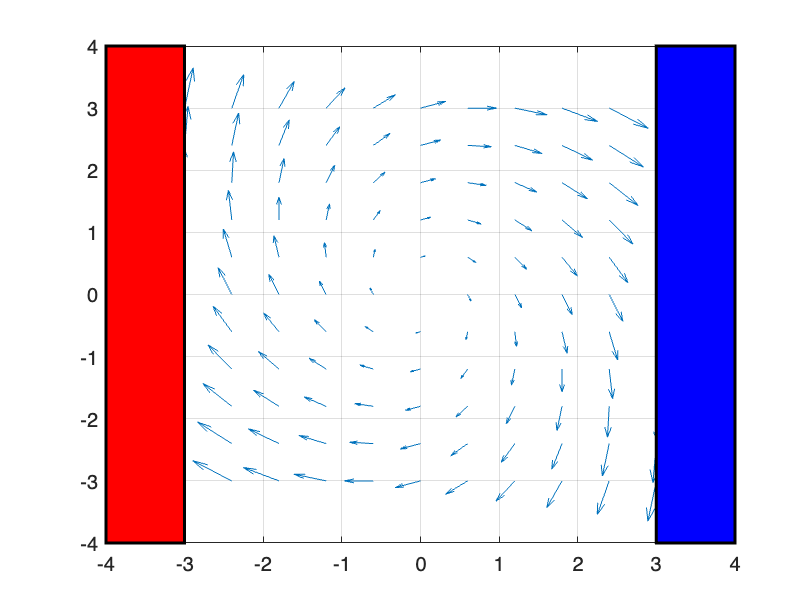

quiver(xx,yy,Ex,Ey);
rectangle('Position', [3 -4 1 8], 'LineWidth', 1.5, 'FaceColor', [0 0 1])
rectangle('Position', [-4 -4 1 8], 'LineWidth', 1.5, 'FaceColor', [1 0 0])
grid on;